clc
clear all


% Csomóponti table
nodesname = ["N1"; "N2"; "N3"; "N4"; "N5"; "N6"; "N7"; "N8"; "N9"; "N10"; "N11"; "N12"; "N13"; "N14"; "N15"];
nodesnp = [190; 70; -80; -60; 200; -40; -130; 0; 120; 130; -150; 60; -170; 40; -120];
nodesnp(end) = -(sum(nodesnp) - nodesnp(end));
nodesx  = [0.0; 0.0; 0.0; 0.0; 2.2; 3.0; 3.0; 4.2; 4.7; 6.8; 7.8; 8.2; 5.8; 6.0; 8.0];
nodesy  = [5.0; 3.7; 2.2; 0.4; 3.4; 2.0; 0.6; 5.1; 3.5; 4.0; 4.7; 2.8; 2.2; 1.0; 0.7];
nodezone = ["A";"A";"B";"B";"A";"B";"B";"C";"C";"C";"C";"D";"D";"D";"D"];

nodes = table(nodesname, nodesnp, nodesx, nodesy, nodezone, 'VariableNames', {'NodeName', 'NP', 'X', 'Y', 'Zone'});

% Vezeték table
edgesname = ["L1"; "L2"; "L3"; "L4"; "L5"; "L6"; "L7"; "L8"; "L9"; "L10"; "L11"; "L12"; "L13"; "L14"; "L15"; "L16"; "L17"; "L18"; "L19"; "L20"; "L21"; "L22"];
edgeslength = [150; 125; 175; 160; 100; 170; 140; 115; 145; 210; 180; 215; 135; 130; 230; 155; 150; 160; 165; 155; 145; 235];
edgesohm = 0.4 * edgeslength;
edgesfrom = ["N1"; "N2"; "N3"; "N4"; "N6"; "N3"; "N3"; "N2"; "N5"; "N1"; "N8"; "N8"; "N9"; "N10"; "N11"; "N10"; "N9"; "N13"; "N6"; "N7"; "N14"; "N12"];
edgesto   = ["N2"; "N3"; "N4"; "N7"; "N7"; "N6"; "N5"; "N5"; "N9"; "N8"; "N9"; "N11"; "N10"; "N11"; "N12"; "N12"; "N13"; "N12"; "N13"; "N14"; "N15"; "N15"];

edges = table(edgesname, edgesohm, edgesfrom, edgesto, 'VariableNames', {'EdgeName', 'Ohm', 'From', 'To'});

% Slack csomópont
slacknodename = "N8";
slacknodeid = find(nodes.NodeName == slacknodename);
sumnp = sum(nodes.NP) - nodes{slacknodeid, "NP"};
slacknodenp = -sumnp;
nodes.NP(slacknodeid) = slacknodenp;

noslacknodesname = nodes.NodeName;
noslacknodesname(slacknodeid) = [];

% Illeszkedési mátrix
A = zeros(height(edges), height(nodes));

for k = 1:height(edges)
    fromid = find(nodes.NodeName == edges.From(k));
    toid = find(nodes.NodeName == edges.To(k));
    A(k, fromid) = 1;
    A(k, toid) = -1;
end

A(:,slacknodeid) = [];
A_table = array2table(A, "RowNames", edgesname, "VariableNames", noslacknodesname)

A_table = 22×14 table
           N1    N2    N3    N4    N5    N6    N7    N9    N10    N11    N12    N13    N14    N15
           __    __    __    __    __    __    __    __    ___    ___    ___    ___    ___    ___

    L1     1     -1     0     0     0     0     0     0     0      0      0      0      0      0 
    L2     0      1    -1     0     0     0     0     0     0      0      0      0      0      0 
    L3     0      0     1    -1     0     0     0     0   


% Vezeték admittancia mátrix
Yline = diag(1./edges.Ohm);
Yline_table = array2table(Yline, "RowNames", edgesname, "VariableNames", edgesname)

Yline_table = 22×22 table
              L1        L2        L3          L4        L5         L6          L7          L8          L9         L10         L11         L12         L13         L14         L15        L16       L17    L18    L19    L20    L21    L22
           ________    ____    ________    ________    _____    ________    ________    ________    ________    ________    ________    ________    ______


% Rendszer mátrixa mátrixszorzással (slack eliminálva)
Y = A'*Yline*A;
Y_table = array2table(Y, "VariableNames", noslacknodesname, "RowNames", noslacknodesname)

Y_table = 14×14 table
              N1           N2           N3           N4           N5           N6           N7           N9           N10          N11          N12          N13          N14          N15   
           _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________

    N1      0.028571    -0.016667            0            0            0            0            0      


% Rendszer mátrixa for ciklussal előállítva
% Y = zeros(height(nodes));
% for k = 1:height(edges)
%     y = 1/edges.Ohm(k);
%     fromid = find(nodes.NodeName == edges.From(k));
%     toid = find(nodes.NodeName == edges.To(k));
%     Y(fromid,fromid) = Y(fromid,fromid) + y;
%     Y(toid,toid) = Y(toid,toid) + y;
%     Y(fromid,toid) = Y(fromid,toid) - y;
%     Y(toid,fromid) = Y(toid,fromid) - y;
% end
% Y(:,slacknodeid) = [];
% Y(slacknodeid,:) = [];


% Node-to-Slack PTDF
nodetoslackPTDF = Yline * A / Y;
ntsPTDF_table = array2table(nodetoslackPTDF, 'VariableNames', noslacknodesname, 'RowNames', edgesname)

ntsPTDF_table = 22×14 table
               N1            N2            N3            N4            N5           N6           N7            N9           N10          N11          N12          N13           N14          N15   
           __________    __________    __________    __________    __________    _________    _________    __________    _________    _________    _________    __________    _________    _________

    L1        0.33209      -0.43069      -0.34408      -0.31012      -0.32852     -0

% NP = Y*theta
% theta = inv(Y)*NP
% F = Yline*A*theta
% F = Yline*A*inv(Y)*NP
% F = PTDF * NP

% Referencia flow (a nem slack csomópontokra)
np = nodes.NP;
np(slacknodeid) = [];
Fr = nodetoslackPTDF * np;
edges.Flowref = Fr;

% Node-to-Node PTDF (a nem slack csomópontokra)
nodefrom = "N1";
nodeto = "N5";

fromid = find(noslacknodesname == nodefrom);
toid   = find(noslacknodesname == nodeto);

ntnvarname = sprintf("%s->%s", nodefrom, nodeto);
nodetonodePTDF = nodetoslackPTDF(:, fromid) - nodetoslackPTDF(:, toid);
ntnPTDF_table = array2table(nodetonodePTDF, "RowNames", edgesname, "VariableNames", ntnvarname)

ntnPTDF_table = 22×1 table
             N1->N5  
           __________

    L1        0.66061
    L2        0.18173
    L3      -0.017066
    L4      -0.017066
    L5     -0.0022584
    L6      -0.032302
    L7         0.2311
    L8        0.47888
    L9       -0.29002
    L10       0.33939
    L11       0.22689
    L12        0.1125
    L13     -0.058127
    L14     -0.067736
    L15      0.044761
    L16     0.0096092



% GSK (egyenletes)
zonenames = ["A","B","C","D"];
zonenum = numel(zonenames);

GSK = zeros(height(nodes), zonenum);

for k = 1:zonenum
    nodeid = find(nodes.Zone == zonenames(k));
    GSK(nodeid,k) = 1 / numel(nodeid);
end

GSK(slacknodeid,:) = [];

% modifiedGSK = GSK;
% modifiedGSK(slacknodeid,:) = modifiedGSK(slacknodeid,:) - 1;

GSK_table = array2table(GSK, "RowNames", noslacknodesname,"VariableNames", zonenames)

GSK_table = 14×4 table
              A        B       C       D  
           _______    ____    ____    ____

    N1     0.33333       0       0       0
    N2     0.33333       0       0       0
    N3           0    0.25       0       0
    N4           0    0.25       0       0
    N5     0.33333       0       0       0
    N6           0    0.25       0       0
    N7           0    0.25       0       0
    N9           0       0    0.25       0
    N10          0       0    0.25       0
    N11          0       0    0.25       0
    N12          0       0       0    0.25
    N13          0       0       0    0.25
    N14          



% Zone-to-Slack PTDF
% nodetoslackPTDF_full = [nodetoslackPTDF(:,1:slacknodeid-1), zeros(size(nodetoslackPTDF,1), 1), nodetoslackPTDF(:,slacknodeid:end)];
% zonetoslackPTDF = nodetoslackPTDF_full * modifiedGSK;

zonetoslackPTDF = nodetoslackPTDF * GSK;

zts_table = array2table(zonetoslackPTDF, "RowNames", edgesname, "VariableNames", zonenames)

zts_table = 22×4 table
               A             B            C             D    
           __________    _________    __________    _________

    L1       -0.14237     -0.30286      -0.11611     -0.21672
    L2        0.11958     -0.28929     -0.054469     -0.16154
    L3       0.056137     -0.20395     -0.018261     -0.11733
    L4       0.056137     0.046047     -0.018261     -0.11733
    L5     -0.0016344     -0.14301    -0.0030201     -0.14978
    L6        0.11158    -0.082491     -0.034209      -0.1431
    L7      -0.048139      0.24715    -0.0019991     0.098897
    L8       0.071378    -0.013567      -0.06164    -0.055187
    L9        0.35657      0.23358     -0.063639     0.043709
    <


% Zone-to-Zone PTDF
zonefrom = "A";
zoneto   = "B";

fromid = find(zonenames == zonefrom, 1);
toid   = find(zonenames == zoneto, 1);

% zonetozonePTDF = nodetoslackPTDF_full * (GSK(:,fromid) - GSK(:,toid));
zonetozonePTDF = nodetoslackPTDF * (GSK(:,fromid) - GSK(:,toid));

ztzvarname = sprintf("%s->%s", zonefrom, zoneto);
ztzPTDF_table = array2table(zonetozonePTDF,"RowNames", edgesname,"VariableNames", ztzvarname)

ztzPTDF_table = 22×1 table
             A->B   
           _________

    L1       0.16049
    L2       0.40888
    L3       0.26009
    L4       0.01009
    L5       0.14137
    L6       0.19408
    L7      -0.29529
    L8      0.084945
    L9       0.12299
    L10      0.17285
    L11     0.085428
    L12     0.087418
    L13     0.048776
    L14    -0.024361
    L15     0.063057
    L16     0.073137




% LODF
LODF = zeros(height(edges),height(edges));
nodetoslackPTDF_full = [nodetoslackPTDF(:,1:slacknodeid-1), zeros(size(nodetoslackPTDF,1), 1), nodetoslackPTDF(:,slacknodeid:end)];
for k = 1:height(edges)

    from = edges.From(k);
    to   = edges.To(k);

    fromid = find(nodesname == from);
    toid   = find(nodesname == to);

    ptdf_ij = nodetoslackPTDF_full(:,fromid) - nodetoslackPTDF_full(:,toid);
    LODF(:,k) = ptdf_ij / (1 - ptdf_ij(k));
    LODF(k,k) = -1;
end

LODF_table = array2table(LODF, "RowNames", edgesname, "VariableNames", edgesname)

LODF_table = 22×22 table
              L1           L2            L3            L4            L5           L6           L7            L8           L9           L10           L11          L12          L13          L14          L15          L16         L17          L18          L19          L20          L21          L22   
           _________    _________    __________    __________    __________    _________    _________    __________    _________    __________

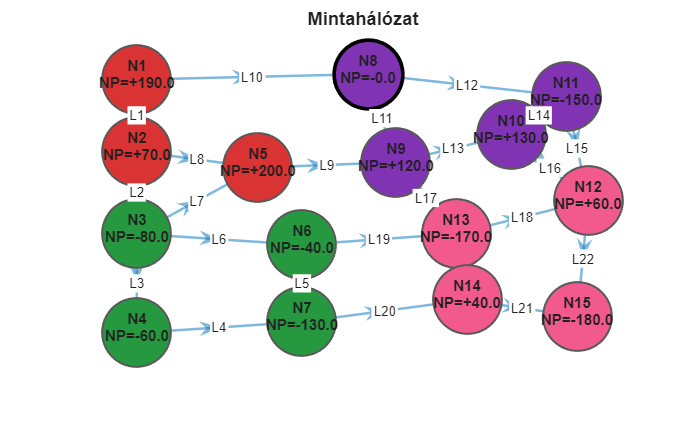





% Hálózat alaprajza
plot_network_from_tables(nodes, edges, slacknodename, 'Mintahálózat');

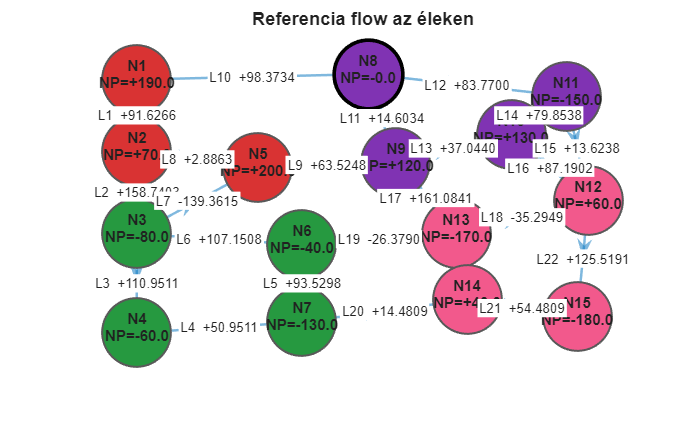


% Adott üzemállapothoz tartozó flow az éleken
plot_edge_values(nodes, edges, edges.Flowref, slacknodename, ...
    'Referencia flow az éleken');

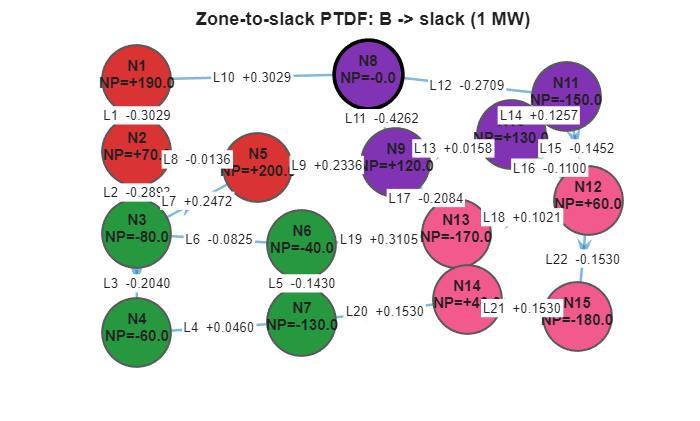


% Zone-to-slack PTDF egy kiválasztott zónára
zoneplot = "B";
zoneid_plot = find(zonenames == zoneplot);
plot_edge_values(nodes, edges, zonetoslackPTDF(:, zoneid_plot), slacknodename, ...
    sprintf('Zone-to-slack PTDF: %s -> slack (1 MW)', char(zoneplot)));

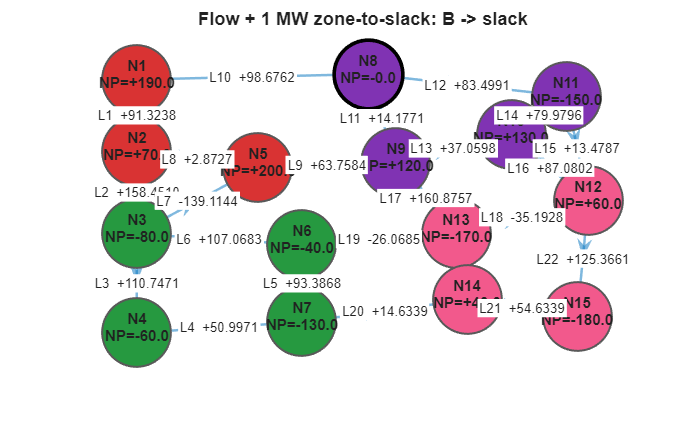


transMW_z2s = 1;
flow_z2s = edges.Flowref + transMW_z2s * zonetoslackPTDF(:, zoneid_plot);
plot_edge_values(nodes, edges, flow_z2s, slacknodename, ...
    sprintf('Flow + %g MW zone-to-slack: %s -> slack', ...
    transMW_z2s, char(zoneplot)));

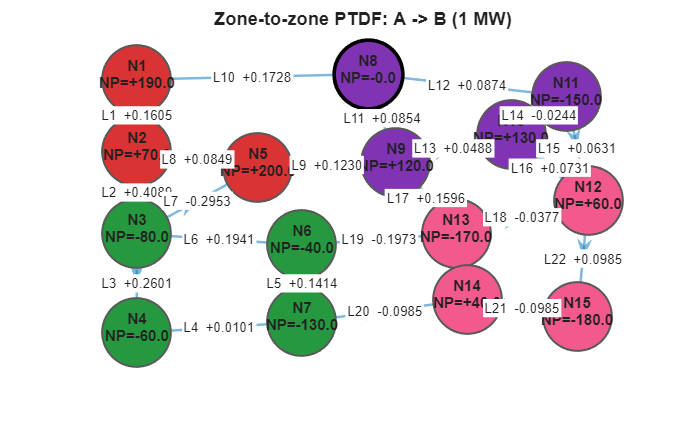


% Zone-to-zone PTDF egy kiválasztott zónapárra
plot_edge_values(nodes, edges, zonetozonePTDF, slacknodename, ...
    sprintf('Zone-to-zone PTDF: %s -> %s (1 MW)', char(zonefrom), char(zoneto)));

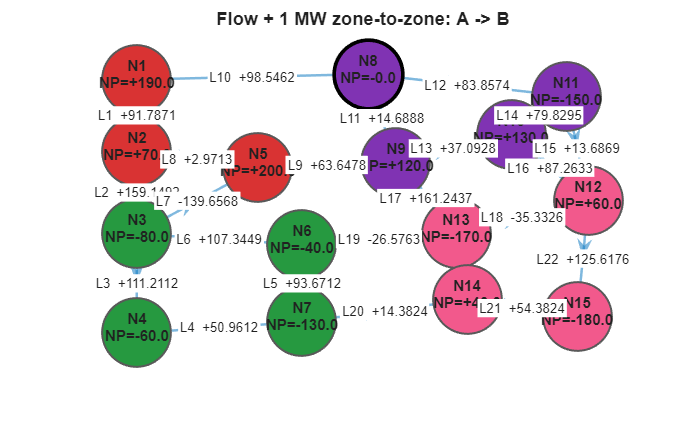


transMW_z2z = 1;
flow_z2z = edges.Flowref + transMW_z2z * zonetozonePTDF;
plot_edge_values(nodes, edges, flow_z2z, slacknodename, ...
    sprintf('Flow + %g MW zone-to-zone: %s -> %s', ...
    transMW_z2z, char(zonefrom), char(zoneto)));

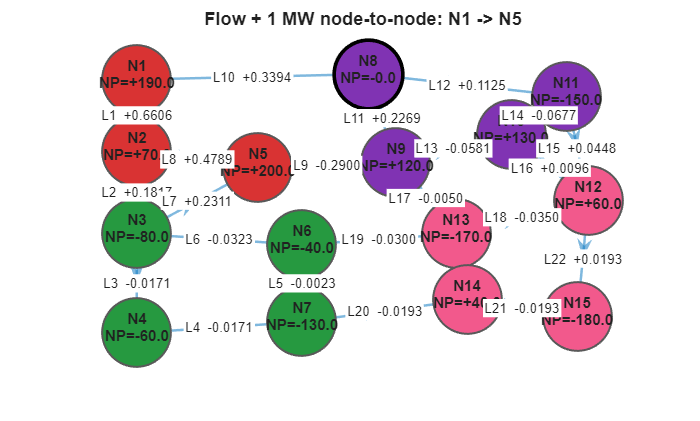


% Node-to-node PTDF
transMW_n2n = 1;
flow_n2n = transMW_n2n * nodetonodePTDF;
plot_edge_values(nodes, edges, flow_n2n, slacknodename, ...
    sprintf('Flow + %g MW node-to-node: %s -> %s', ...
    transMW_n2n, char(nodefrom), char(nodeto)));

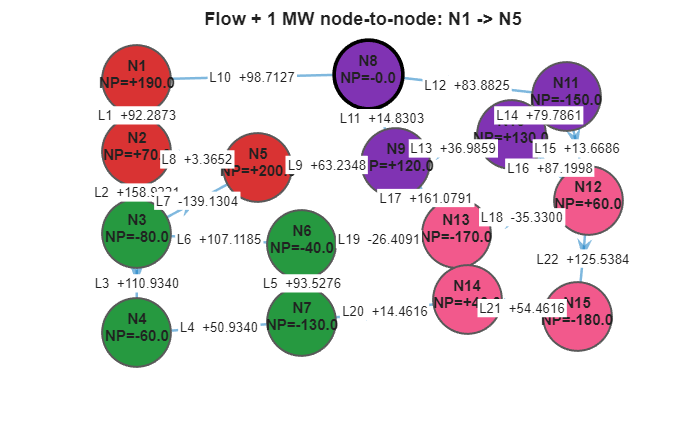


% Node-to-node PTDF után flow
transMW_n2n = 1;
flow_n2n = edges.Flowref + transMW_n2n * nodetonodePTDF;
plot_edge_values(nodes, edges, flow_n2n, slacknodename, ...
    sprintf('Flow + %g MW node-to-node: %s -> %s', ...
    transMW_n2n, char(nodefrom), char(nodeto)));

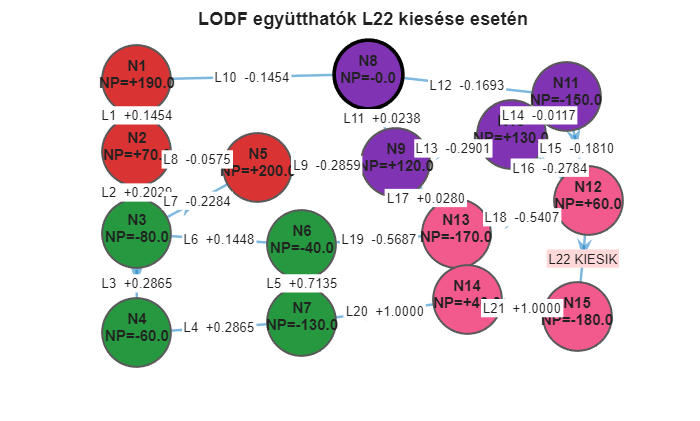


% LODF / kontingencia egy kiválasztott kieső vezetékre
outageline = "L22";
outageid = find(edges.EdgeName == outageline);

plot_lodf_case(nodes, edges, LODF(:, outageid), outageid, slacknodename, ...
    sprintf('LODF együtthatók %s kiesése esetén', outageline));

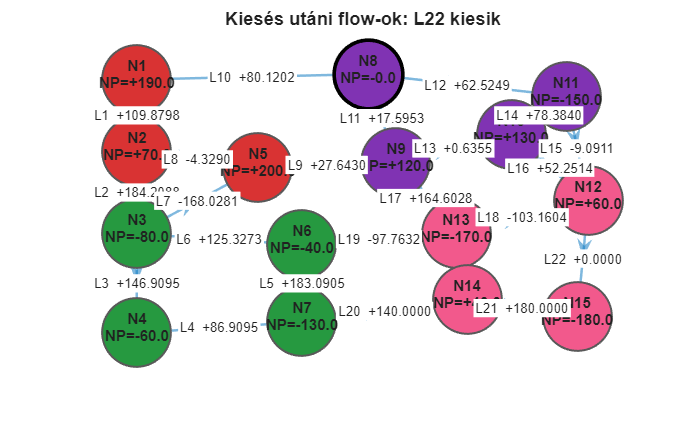


% Ha a kiesés utáni flow-változást is akarod a referencia-flowból:
postContFlow = edges.Flowref + LODF(:, outageid) * edges.Flowref(outageid);
postContFlow(outageid) = 0;

plot_edge_values(nodes, edges, postContFlow, slacknodename, ...
    sprintf('Kiesés utáni flow-ok: %s kiesik', outageline));


function plot_network_from_tables(nodes, edges, slacknodename, figTitle)

    G = digraph(cellstr(edges.From), cellstr(edges.To), ones(height(edges),1), cellstr(nodes.NodeName));

    figure('Color','w')
    p = plot(G, ...
        'XData', nodes.X, ...
        'YData', nodes.Y, ...
        'LineWidth', 1.5, ...
        'ArrowSize', 12);

    p.NodeLabel = repmat({''}, height(nodes), 1);
    p.EdgeLabel = repmat({''}, height(edges), 1);

    axis equal
    axis off
    title(figTitle, 'Interpreter','none')

    hold on

    nodeColors = get_zone_colors(nodes.Zone);

    for k = 1:height(nodes)
        if nodes.NodeName(k) == slacknodename
            edgeColor = [0 0 0];
            lw = 2.2;
        else
            edgeColor = [0.35 0.35 0.35];
            lw = 1.2;
        end

        scatter(nodes.X(k), nodes.Y(k), 1700, ...
            'MarkerFaceColor', nodeColors(k,:), ...
            'MarkerEdgeColor', edgeColor, ...
            'LineWidth', lw);

        txt = sprintf('%s\nNP=%+.1f', nodes.NodeName(k), nodes.NP(k));
        text(nodes.X(k), nodes.Y(k)+0.10, txt, ...
            'HorizontalAlignment','center', ...
            'FontWeight','bold', ...
            'FontSize',9, ...
            'Interpreter','none');
    end

    for ell = 1:height(edges)
        i = find(nodes.NodeName == edges.From(ell), 1);
        j = find(nodes.NodeName == edges.To(ell), 1);

        midX = 0.5 * (nodes.X(i) + nodes.X(j));
        midY = 0.5 * (nodes.Y(i) + nodes.Y(j));

        text(midX, midY, char(edges.EdgeName(ell)), ...
            'HorizontalAlignment','center', ...
            'BackgroundColor','w', ...
            'Margin',1, ...
            'FontSize',8, ...
            'Interpreter','none');
    end

    hold off
end

function plot_edge_values(nodes, edges, edgeValues, slacknodename, figTitle)

    G = digraph(cellstr(edges.From), cellstr(edges.To), ones(height(edges),1), cellstr(nodes.NodeName));

    figure('Color','w')
    p = plot(G, ...
        'XData', nodes.X, ...
        'YData', nodes.Y, ...
        'LineWidth', 1.5, ...
        'ArrowSize', 12);

    p.NodeLabel = repmat({''}, height(nodes), 1);
    p.EdgeLabel = repmat({''}, height(edges), 1);

    axis equal
    axis off
    title(figTitle, 'Interpreter','none')

    hold on

    nodeColors = get_zone_colors(nodes.Zone);

    for k = 1:height(nodes)
        if nodes.NodeName(k) == slacknodename
            edgeColor = [0 0 0];
            lw = 2.2;
        else
            edgeColor = [0.35 0.35 0.35];
            lw = 1.2;
        end

        scatter(nodes.X(k), nodes.Y(k), 1700, ...
            'MarkerFaceColor', nodeColors(k,:), ...
            'MarkerEdgeColor', edgeColor, ...
            'LineWidth', lw);

        txtNode = sprintf('%s\nNP=%+.1f', char(nodes.NodeName(k)), nodes.NP(k));
        text(nodes.X(k), nodes.Y(k)+0.10, txtNode, ...
            'HorizontalAlignment','center', ...
            'FontWeight','bold', ...
            'FontSize',9, ...
            'Interpreter','none');
    end

    for ell = 1:height(edges)
        i = find(nodes.NodeName == edges.From(ell), 1);
        j = find(nodes.NodeName == edges.To(ell), 1);

        midX = 0.5 * (nodes.X(i) + nodes.X(j));
        midY = 0.5 * (nodes.Y(i) + nodes.Y(j));

        txt = sprintf('%s  %+.4f', edges.EdgeName(ell), edgeValues(ell));

        text(midX, midY, txt, ...
            'HorizontalAlignment','center', ...
            'BackgroundColor','w', ...
            'Margin',1, ...
            'FontSize',8, ...
            'Interpreter','none');
    end

    hold off
end

function plot_lodf_case(nodes, edges, lodfVec, outageid, slacknodename, figTitle)

    G = digraph(cellstr(edges.From), cellstr(edges.To), ones(height(edges),1), cellstr(nodes.NodeName));

    figure('Color','w')
    p = plot(G, ...
        'XData', nodes.X, ...
        'YData', nodes.Y, ...
        'LineWidth', 1.5, ...
        'ArrowSize', 12);

    p.NodeLabel = repmat({''}, height(nodes), 1);
    p.EdgeLabel = repmat({''}, height(edges), 1);

    axis equal
    axis off
    title(figTitle, 'Interpreter','none')

    hold on

    nodeColors = get_zone_colors(nodes.Zone);

    for k = 1:height(nodes)
        if nodes.NodeName(k) == slacknodename
            edgeColor = [0 0 0];
            lw = 2.2;
        else
            edgeColor = [0.35 0.35 0.35];
            lw = 1.2;
        end

        scatter(nodes.X(k), nodes.Y(k), 1700, ...
            'MarkerFaceColor', nodeColors(k,:), ...
            'MarkerEdgeColor', edgeColor, ...
            'LineWidth', lw);

        txtNode = sprintf('%s\nNP=%+.1f', char(nodes.NodeName(k)), nodes.NP(k));
        text(nodes.X(k), nodes.Y(k)+0.10, txtNode, ...
            'HorizontalAlignment','center', ...
            'FontWeight','bold', ...
            'FontSize',9, ...
            'Interpreter','none');
    end

    for ell = 1:height(edges)
        i = find(nodes.NodeName == edges.From(ell), 1);
        j = find(nodes.NodeName == edges.To(ell), 1);

        midX = 0.5 * (nodes.X(i) + nodes.X(j));
        midY = 0.5 * (nodes.Y(i) + nodes.Y(j));

        if ell == outageid
            txt = sprintf('%s KIESIK', edges.EdgeName(ell));
            bgc = [1.0 0.85 0.85];
        else
            txt = sprintf('%s  %+.4f', edges.EdgeName(ell), lodfVec(ell));
            bgc = 'w';
        end

        text(midX, midY, txt, ...
            'HorizontalAlignment','center', ...
            'BackgroundColor', bgc, ...
            'Margin',1, ...
            'FontSize',8, ...
            'Interpreter','none');
    end

    hold off
end

function nodeColors = get_zone_colors(zoneVec)

    nodeColors = zeros(numel(zoneVec), 3);

    for k = 1:numel(zoneVec)
        switch char(zoneVec(k))
            case 'A'
                nodeColors(k,:) = [0.85 0.20 0.20];
            case 'B'
                nodeColors(k,:) = [0.15 0.60 0.25];
            case 'C'
                nodeColors(k,:) = [0.50 0.20 0.70];
            case 'D'
                nodeColors(k,:) = [0.95 0.35 0.55];
            otherwise
                nodeColors(k,:) = [0.5 0.5 0.5];
        end
    end
end